sqz = squeezenet;
lgraphSqz = layerGraph(sqz);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])

Number of Layers: 68


disp(lgraphSqz.Layers(1).InputSize)

   227   227     3



lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                  50% dropout
     2   'conv10'                            Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                     ReLU
     4   'pool10'                            Global Average Pooling   Global average pooling
     5   'prob'                              Softmax                  softmax
     6   'ClassificationLayer_predictions'   Classification Output    crossentropyex with 'tench' and 999 other classes

tmpLayer = lgraphSqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
tmpLayer = lgraphSqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);

tmpLayer = lgraphSqz.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

lgraphSqz.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                  60% dropout
     2   'new_conv'          Convolution              2 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                     ReLU
     4   'pool10'            Global Average Pooling   Global average pooling
     5   'prob'              Softmax                  softmax
     6   'new_classoutput'   Classification Output    crossentropyex


augimgsTrain = augmentedImageDatastore([227 227],imgsTrain);
augimgsValidation = augmentedImageDatastore([227 227],imgsValidation);

ilr = 3e-4;
miniBatchSize = 10;
maxEpochs = 15;
valFreq = floor(numel(augimgsTrain.Files)/miniBatchSize);
opts = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'ValidationData',augimgsValidation,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress');

rng default
trainedSN = trainNetwork(augimgsTrain,lgraphSqz,opts);

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:17 |       50.00% |       55.25% |       0.9935 |       0.8309 |          0.0003 |


|       1 |          50 |       00:00:25 |       80.00% |              |       0.7276 |              |          0.0003 |


|       1 |         100 |       00:00:32 |      100.00% |              |       0.0866 |              |          0.0003 |


|       1 |         150 |       00:00:40 |      100.00% |              |       0.1526 |              |          0.0003 |


|       1 |         200 |       00:00:47 |       90.00% |              |       0.4853 |              |          0.0003 |


|       1 |         250 |       00:00:55 |      100.00% |              |       0.2034 |              |          0.0003 |


|       1 |         300 |       00:01:02 |       90.00% |              |       0.1658 |              |          0.0003 |


|       1 |         320 |       00:01:15 |       80.00% |       92.25% |       0.2866 |       0.2138 |          0.0003 |


|       2 |         350 |       00:01:20 |      100.00% |              |       0.0439 |              |          0.0003 |


|       2 |         400 |       00:01:27 |      100.00% |              |       0.0551 |              |          0.0003 |


|       2 |         450 |       00:01:35 |       90.00% |              |       0.1473 |              |          0.0003 |


|       2 |         500 |       00:01:43 |       90.00% |              |       0.2353 |              |          0.0003 |


|       2 |         550 |       00:01:50 |       90.00% |              |       0.1052 |              |          0.0003 |


|       2 |         600 |       00:01:58 |       90.00% |              |       0.2912 |              |          0.0003 |


|       2 |         640 |       00:02:14 |       70.00% |       91.63% |       0.5501 |       0.2588 |          0.0003 |


|       3 |         650 |       00:02:15 |       70.00% |              |       0.4457 |              |          0.0003 |


|       3 |         700 |       00:02:23 |       90.00% |              |       0.4888 |              |          0.0003 |


|       3 |         750 |       00:02:30 |      100.00% |              |       0.1261 |              |          0.0003 |


|       3 |         800 |       00:02:38 |      100.00% |              |       0.0162 |              |          0.0003 |


|       3 |         850 |       00:02:45 |       90.00% |              |       0.1584 |              |          0.0003 |


|       3 |         900 |       00:02:53 |      100.00% |              |       0.0614 |              |          0.0003 |


|       3 |         950 |       00:03:00 |      100.00% |              |       0.0402 |              |          0.0003 |


|       3 |         960 |       00:03:11 |      100.00% |       94.13% |       0.1260 |       0.1757 |          0.0003 |


|       4 |        1000 |       00:03:17 |      100.00% |              |       0.0118 |              |          0.0003 |


|       4 |        1050 |       00:03:25 |       90.00% |              |       0.6503 |              |          0.0003 |


|       4 |        1100 |       00:03:32 |       90.00% |              |       0.4420 |              |          0.0003 |


|       4 |        1150 |       00:03:40 |      100.00% |              |       0.0311 |              |          0.0003 |


|       4 |        1200 |       00:03:48 |      100.00% |              |       0.0094 |              |          0.0003 |


|       4 |        1250 |       00:03:55 |       90.00% |              |       0.2143 |              |          0.0003 |


|       4 |        1280 |       00:04:09 |      100.00% |       94.63% |       0.0247 |       0.1285 |          0.0003 |


|       5 |        1300 |       00:04:12 |      100.00% |              |       0.0613 |              |          0.0003 |


|       5 |        1350 |       00:04:19 |      100.00% |              |       0.0282 |              |          0.0003 |


|       5 |        1400 |       00:04:27 |       80.00% |              |       0.4165 |              |          0.0003 |


|       5 |        1450 |       00:04:34 |      100.00% |              |       0.0535 |              |          0.0003 |


|       5 |        1500 |       00:04:42 |      100.00% |              |       0.0619 |              |          0.0003 |


|       5 |        1550 |       00:04:49 |      100.00% |              |       0.0167 |              |          0.0003 |


|       5 |        1600 |       00:05:07 |      100.00% |       94.50% |       0.0670 |       0.1486 |          0.0003 |


|       6 |        1650 |       00:05:14 |      100.00% |              |       0.0468 |              |          0.0003 |


|       6 |        1700 |       00:05:22 |       90.00% |              |       0.1134 |              |          0.0003 |


|       6 |        1750 |       00:05:29 |      100.00% |              |       0.0681 |              |          0.0003 |


|       6 |        1800 |       00:05:37 |      100.00% |              |       0.0605 |              |          0.0003 |


|       6 |        1850 |       00:05:44 |      100.00% |              |       0.0096 |              |          0.0003 |


|       6 |        1900 |       00:05:51 |      100.00% |              |       0.0258 |              |          0.0003 |


|       6 |        1920 |       00:06:04 |      100.00% |       94.25% |       0.0285 |       0.1601 |          0.0003 |


|       7 |        1950 |       00:06:09 |      100.00% |              |       0.0007 |              |          0.0003 |


|       7 |        2000 |       00:06:16 |      100.00% |              |       0.0002 |              |          0.0003 |


|       7 |        2050 |       00:06:24 |      100.00% |              |       0.0223 |              |          0.0003 |


|       7 |        2100 |       00:06:31 |      100.00% |              |       0.0257 |              |          0.0003 |


|       7 |        2150 |       00:06:39 |       90.00% |              |       0.0888 |              |          0.0003 |


|       7 |        2200 |       00:06:46 |       90.00% |              |       0.2089 |              |          0.0003 |


|       7 |        2240 |       00:07:03 |       90.00% |       95.63% |       0.1241 |       0.1383 |          0.0003 |


|       8 |        2250 |       00:07:05 |      100.00% |              |       0.0233 |              |          0.0003 |


|       8 |        2300 |       00:07:12 |       90.00% |              |       0.3051 |              |          0.0003 |


|       8 |        2350 |       00:07:20 |      100.00% |              |       0.0067 |              |          0.0003 |


|       8 |        2400 |       00:07:28 |      100.00% |              |       0.0004 |              |          0.0003 |


|       8 |        2450 |       00:07:35 |      100.00% |              |       0.0048 |              |          0.0003 |


|       8 |        2500 |       00:07:43 |       90.00% |              |       0.2376 |              |          0.0003 |


|       8 |        2550 |       00:07:50 |      100.00% |              |       0.0381 |              |          0.0003 |


|       8 |        2560 |       00:08:01 |       90.00% |       96.50% |       0.1060 |       0.1035 |          0.0003 |


|       9 |        2600 |       00:08:08 |      100.00% |              |       0.0053 |              |          0.0003 |


|       9 |        2650 |       00:08:15 |      100.00% |              |       0.0180 |              |          0.0003 |


|       9 |        2700 |       00:08:23 |      100.00% |              |       0.0422 |              |          0.0003 |


|       9 |        2750 |       00:08:30 |      100.00% |              |       0.0013 |              |          0.0003 |


|       9 |        2800 |       00:08:38 |      100.00% |              |       0.0014 |              |          0.0003 |


|       9 |        2850 |       00:08:45 |      100.00% |              |       0.0217 |              |          0.0003 |


|       9 |        2880 |       00:08:59 |       90.00% |       94.00% |       0.1174 |       0.1624 |          0.0003 |


|      10 |        2900 |       00:09:02 |      100.00% |              |       0.0275 |              |          0.0003 |


|      10 |        2950 |       00:09:10 |      100.00% |              |       0.0129 |              |          0.0003 |


|      10 |        3000 |       00:09:18 |       90.00% |              |       0.1016 |              |          0.0003 |


|      10 |        3050 |       00:09:25 |       90.00% |              |       0.0719 |              |          0.0003 |


|      10 |        3100 |       00:09:33 |      100.00% |              |       0.0198 |              |          0.0003 |


|      10 |        3150 |       00:09:42 |      100.00% |              |   2.3007e-06 |              |          0.0003 |


|      10 |        3200 |       00:10:01 |      100.00% |       98.13% |       0.0529 |       0.0874 |          0.0003 |


|      11 |        3250 |       00:10:09 |      100.00% |              |       0.0109 |              |          0.0003 |


|      11 |        3300 |       00:10:16 |      100.00% |              |   8.9409e-06 |              |          0.0003 |


|      11 |        3350 |       00:10:24 |      100.00% |              |       0.0231 |              |          0.0003 |


|      11 |        3400 |       00:10:31 |      100.00% |              |       0.0065 |              |          0.0003 |


|      11 |        3450 |       00:10:39 |      100.00% |              |       0.0001 |              |          0.0003 |


|      11 |        3500 |       00:10:46 |       90.00% |              |       0.1248 |              |          0.0003 |


|      11 |        3520 |       00:10:59 |      100.00% |       94.25% |       0.0352 |       0.1391 |          0.0003 |


|      12 |        3550 |       00:11:03 |      100.00% |              |       0.0014 |              |          0.0003 |


|      12 |        3600 |       00:11:11 |      100.00% |              |       0.0003 |              |          0.0003 |


|      12 |        3650 |       00:11:18 |       90.00% |              |       0.4131 |              |          0.0003 |


|      12 |        3700 |       00:11:25 |      100.00% |              |       0.0310 |              |          0.0003 |


|      12 |        3750 |       00:11:32 |      100.00% |              |       0.0147 |              |          0.0003 |


|      12 |        3800 |       00:11:40 |      100.00% |              |       0.0033 |              |          0.0003 |


|      12 |        3840 |       00:11:55 |      100.00% |       98.75% |       0.0614 |       0.0553 |          0.0003 |


|      13 |        3850 |       00:11:57 |      100.00% |              |       0.0026 |              |          0.0003 |


|      13 |        3900 |       00:12:05 |      100.00% |              |       0.0230 |              |          0.0003 |


|      13 |        3950 |       00:12:12 |      100.00% |              |       0.0004 |              |          0.0003 |


|      13 |        4000 |       00:12:20 |      100.00% |              |   7.6772e-06 |              |          0.0003 |


|      13 |        4050 |       00:12:27 |      100.00% |              |       0.0008 |              |          0.0003 |


|      13 |        4100 |       00:12:35 |      100.00% |              |   5.5672e-06 |              |          0.0003 |


|      13 |        4150 |       00:12:42 |      100.00% |              |   1.4544e-06 |              |          0.0003 |


|      13 |        4160 |       00:12:53 |      100.00% |       98.13% |       0.0056 |       0.0834 |          0.0003 |


|      14 |        4200 |       00:13:00 |      100.00% |              |       0.0001 |              |          0.0003 |


|      14 |        4250 |       00:13:07 |      100.00% |              |   8.7005e-05 |              |          0.0003 |


|      14 |        4300 |       00:13:15 |      100.00% |              |       0.0052 |              |          0.0003 |


|      14 |        4350 |       00:13:23 |      100.00% |              |       0.0003 |              |          0.0003 |


|      14 |        4400 |       00:13:30 |      100.00% |              |       0.0012 |              |          0.0003 |


|      14 |        4450 |       00:13:38 |      100.00% |              |       0.0018 |              |          0.0003 |


|      14 |        4480 |       00:13:52 |      100.00% |       95.75% |       0.0474 |       0.1282 |          0.0003 |


|      15 |        4500 |       00:13:55 |       90.00% |              |       0.1126 |              |          0.0003 |


|      15 |        4550 |       00:14:03 |      100.00% |              |   1.0801e-05 |              |          0.0003 |


|      15 |        4600 |       00:14:10 |      100.00% |              |       0.0230 |              |          0.0003 |


|      15 |        4650 |       00:14:18 |      100.00% |              |       0.0003 |              |          0.0003 |


|      15 |        4700 |       00:14:25 |      100.00% |              |       0.0015 |              |          0.0003 |


|      15 |        4750 |       00:14:33 |      100.00% |              |  -0.0000e+00 |              |          0.0003 |


|      15 |        4800 |       00:14:51 |      100.00% |       98.38% |       0.0036 |       0.0485 |          0.0003 |


|======================================================================================================================|



[YPred,probs] = classify(trainedSN,augimgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 98.375%


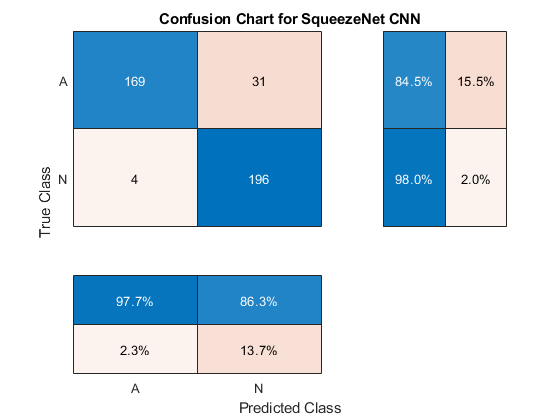


augimgsTesting = augmentedImageDatastore([227 227],testing);

Pred2 = classify(trainedSN, augimgsTesting);
confusionchart(testing.Labels,Pred2,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for SqueezeNet CNN');

cfsmat2 = confusionmat(testing.Labels,Pred2);
[acc2, p2, r2, f1_2] = predictionScores(cfsmat2);
disp(['Accuracy: ', num2str(100*acc2),'%']);

Accuracy: 91.25%


disp(['Precision: ', num2str(p2)]);

Precision: 0.97688


disp(['Recall: ',num2str(r2)]);

Recall: 0.845


disp(['F1 score: ', num2str(f1_2)]);

F1 score: 0.90617
